n = 5; m = 10; d = 3; 

% G1: balanced graph
s = [1 1 2 2 3 3 4 4 5 5];
t = [2 3 3 4 4 5 5 1 1 2];
G1 = graph(s,t); %plot(G1);
A1 = [1 0 0;
      0 1 0;
      0 0 0];
A2 = [0 0 0;
      0 0 0;
      0 0 1];
Z = zeros(3,3);
A = [Z  A1  A2   Z   Z;
     Z   Z  A1  A2   Z;
     Z   Z   Z  A1  A2;
     A2  Z   Z   Z  A1;
     A1 A2   Z   Z   Z];
E = A*(kron(ones(5,1),eye(3)));
D = blkdiag(E(1:3,1:3),E(4:6,1:3),E(7:9,1:3),E(10:12,1:3),E(13:15,1:3));
L = D - A;

rng(1)

x0 = [];   % the agents are initially located on the unit sphere
for i = 1:5
    r = 4*(rand(3,1)-0.5);
    x0 = [x0;r/norm(r)];
end
N = 41;
t = 0:N-1; t = t';
x = zeros(d*n,N);
e = zeros(1,N);
x(:,1) = x0;
e(:,1) = norm(L*x0);

% delta = 0.3
delta = 0.3

delta = 0.3000

W = eye(d*n) - delta*L;
reshape(eig(W),3,5)

ans =    0.4573 + 0.1763i   0.7927 - 0.2853i   0.4573 - 0.1763i   1.0000 + 0.0000i   0.7927 + 0.2853i
   0.4573 - 0.1763i   1.0000 + 0.0000i   0.7927 + 0.2853i   0.4573 + 0.1763i   0.7927 - 0.2853i
   0.7927 + 0.2853i   0.4573 + 0.1763i   0.7927 - 0.2853i   0.4573 - 0.1763i   1.0000 + 0.0000i


max(1.-abs(eig(W)))

ans = 0.5099

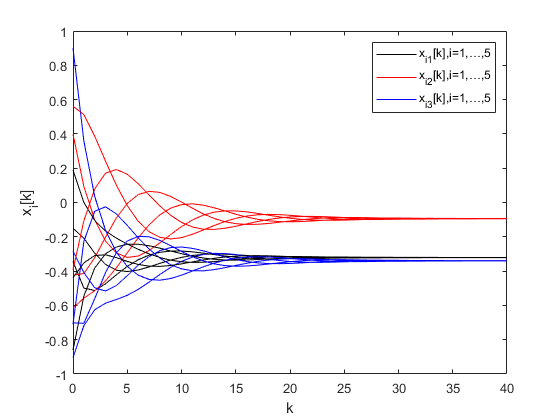


for k=1:N-1
    x(:,k+1) = W*x(:,k);
    e(:,k) = norm(L*x(:,k+1));
end

% plotting the states versus time
figure(1)
hold on;
for i=1:5
   plot(t,x(3*i-2,:),'-k');
   plot(t,x(3*i-1,:),'-r');
   plot(t,x(3*i-0,:),'-b');
end
xlabel 'k'; ylabel 'x_i[k]';
box on;
legend({'x_{i1}[k],i=1,\ldots,5','x_{i2}[k],i=1,\ldots,5','x_{i3}[k],i=1,\ldots,5'},"NumColumns",1);

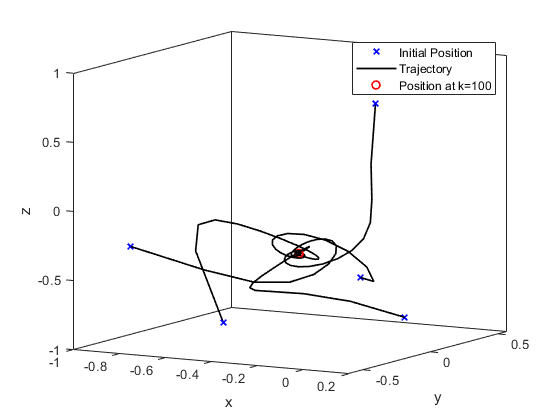


figure
hold on;
for i=1:5
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','LineWidth',1.25);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',1.25);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','LineWidth',1.25);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
box on
legend({'Initial Position','Trajectory','Position at k=100'},"NumColumns",1)
view(30,10)

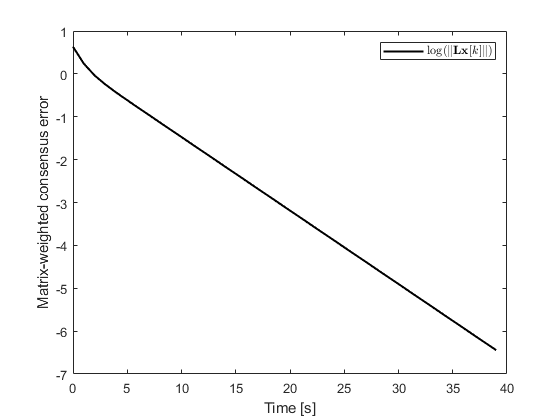

figure
plot(t,log(e)','-k','LineWidth',1.5)
xlabel 'Time [s]'; ylabel 'Matrix-weighted consensus error';
box on; 
legend({'$\log(\|\mathbf{L}\mathbf{x}[k]\|)$'},"Interpreter",'latex',"NumColumns",1)

% delta = 0.8
delta = .8

delta = 0.8000

W = eye(d*n) - delta*L;
reshape(eig(W),3,5)

ans =   -0.4472 + 0.4702i   0.4472 - 0.7608i  -0.4472 - 0.4702i   1.0000 + 0.0000i   0.4472 + 0.7608i
  -0.4472 - 0.4702i   1.0000 + 0.0000i   0.4472 + 0.7608i  -0.4472 + 0.4702i   0.4472 - 0.7608i
   0.4472 + 0.7608i  -0.4472 + 0.4702i   0.4472 - 0.7608i  -0.4472 - 0.4702i   1.0000 + 0.0000i


max(1.-abs(eig(W)))

ans = 0.3511

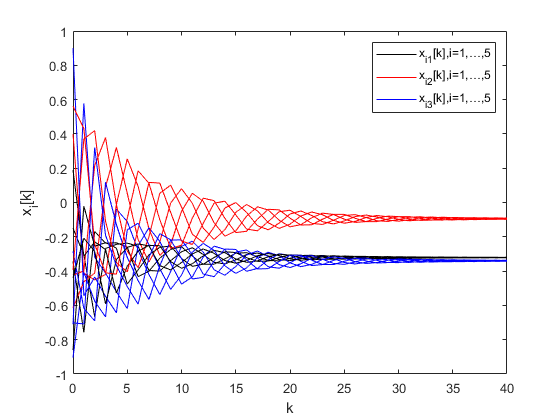

for k=1:N-1
    x(:,k+1) = W*x(:,k);
    e(:,k) = norm(L*x(:,k+1));
end

% plotting the states versus time
figure
hold on;
for i=1:5
   plot(t,x(3*i-2,:),'-k');
   plot(t,x(3*i-1,:),'-r');
   plot(t,x(3*i,:),'-b');
end
xlabel 'k'; ylabel 'x_i[k]';
box on;
legend({'x_{i1}[k],i=1,\ldots,5','x_{i2}[k],i=1,\ldots,5','x_{i3}[k],i=1,\ldots,5'},"NumColumns",1)

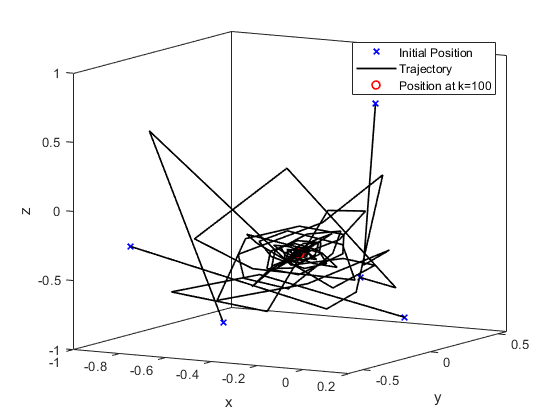

figure
hold on;
for i=1:5
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','LineWidth',1.25);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',1.25);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','LineWidth',1.25);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
box on
legend({'Initial Position','Trajectory','Position at k=100'},"NumColumns",1)
view(30,10)

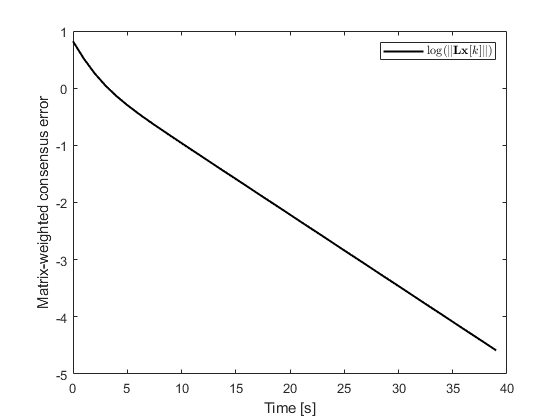

figure
plot(t,log(e)','-k','LineWidth',1.5)
xlabel 'Time [s]'; ylabel 'Matrix-weighted consensus error';
box on; 
legend({'$\log(\|\mathbf{L}\mathbf{x}[k]\|)$'},"Interpreter",'latex',"NumColumns",1)

% delta = 1
delta = 1.0

delta = 1

W = eye(d*n) - delta*L;
reshape(abs(eig(W)),3,5)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000


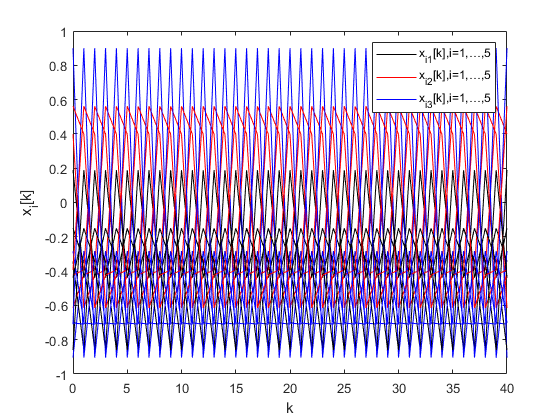

for k=1:N-1
    x(:,k+1) = W*x(:,k);
    e(:,k) = norm(L*x(:,k+1));
end

% plotting the states versus time
figure
hold on;
for i=1:5
   plot(t,x(3*i-2,:),'-k');
   plot(t,x(3*i-1,:),'-r');
   plot(t,x(3*i,:),'-b');
end
xlabel 'k'; ylabel 'x_i[k]';
box on;
legend({'x_{i1}[k],i=1,\ldots,5','x_{i2}[k],i=1,\ldots,5','x_{i3}[k],i=1,\ldots,5'},"NumColumns",1)

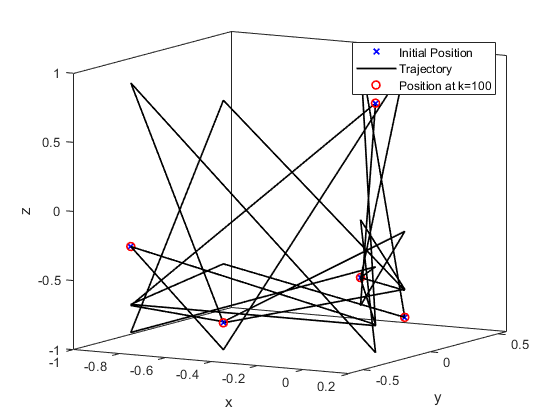

figure
hold on;
for i=1:5
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','LineWidth',1.25);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',1.25);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','LineWidth',1.25);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
box on
legend({'Initial Position','Trajectory','Position at k=100'},"NumColumns",1)
view(30,10)

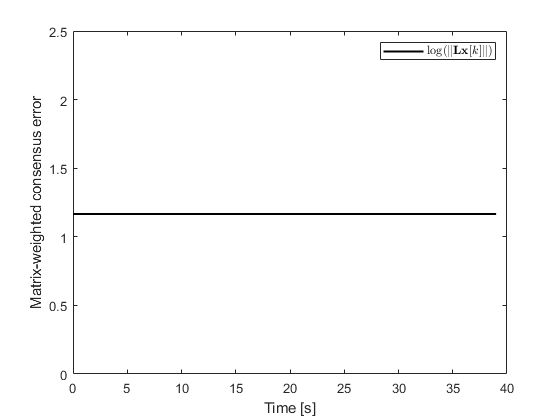

figure
plot(t,log(e)','-k','LineWidth',1.5)
xlabel 'Time [s]'; ylabel 'Matrix-weighted consensus error';
box on; 
legend({'$\log(\|\mathbf{L}\mathbf{x}[k]\|)$'},"Interpreter",'latex',"NumColumns",1)